clc;
clear all;
close all;


tolr = 1d-8;
tolq = 1d-8;

global  Lx Lz alpha_eq1 alpha_eq2 alpha_eq3 alpha_eq4 Bz_min Bz_max B_lobe  EE4 B_e x_eq1 x_eq2 x_eq3  x0;



%--------------
% constant
Lx = 0.082;
Lz = 0.741455;
Bz_min = 5.495;
Bz_max = 10.02;
B_lobe = 34.91;
B_e = -30600;
x0 = - 10.0;

%--------------
% 
alpha_eq1 = pi/12;
alpha_eq2 = pi/8;
alpha_eq3 = pi/6;
alpha_eq4 = pi/5;
alpha_eq5 = pi/4;
alpha_eq6 = pi/3.5;
alpha_eq7 = pi/3;
alpha_eq8 = pi/2.5;
alpha_eq9 = pi/2.3;
alpha_eq10 = pi/2.15;

EE4 = 100.0;

x_eq1 = -10.09799;
x_eq2 = - 10.0;
x_eq3 = -9.9;

%initial values
x00 = x_eq1;
x01 = x_eq2;
x02 = x_eq3;

tic;

ikmax=1

ikmax = 1

Tf1=3;
%Tf=Tf1*ikmax;
Tf0= 0.0;

options = odeset('RelTol',tolr,'AbsTol',tolr);

step= 1;

for ik=1:ikmax
   
[T1,Y1] = ode45(@bysyst,[Tf0 Tf0+Tf1],[x00 x01 x02],options);

ld=length(Y1(:,1));

ik1=ik

x00=Y1(ld,1);
x01=Y1(ld,2);
x02=Y1(ld,3);
Tf0=T1(ld);

Y11=Y1(1:step:ld,:); T11=T1(1:step:ld);

if ik==1 Y=Y11; T=T11; else Y=cat(1,Y,Y11); T=cat(1,T,T11); end

end

ik1 = 1


ld=length(Y(:,1));

% ld=10; 

z=T(1:step:ld);
z

z =          0
    0.0154
    0.0308
    0.0462
    0.0616
    0.0770
    0.0924
    0.1078
    0.1232
    0.1365


x=Y(1:step:ld,1);
x1=Y(1:step:ld,2);
x2=Y(1:step:ld,3);



f1_1 = (((B_e)*((1./sqrt((x.^2)+(z.^2))).^3).*(3.*x.*z))./((x.^2)+(z.^2)));
f2_1 = (((B_e)*((1./sqrt((x.^2)+(z.^2))).^3).*((2.*(z.^2)-(x.^2))./((x.^2)+(z.^2))))).*((0.5.* (1 + tanh( (x) +9) ) ));
f3_1 = (B_lobe.*tanh(z./Lz));
f4_1 = (Bz_min+(0.5).*(Bz_max-Bz_min).*(1+tanh((-x + x0)./ Lx)));

f1_2 = (((B_e)*((1./sqrt((x1.^2)+(z.^2))).^3).*(3.*x1.*z))./((x1.^2)+(z.^2)));
f2_2 = (((B_e)*((1./sqrt((x1.^2)+(z.^2))).^3).*((2.*(z.^2)-(x1.^2))./((x1.^2)+(z.^2))))).*((0.5.* (1 + tanh( (x1) +9) ) ));
f3_2 = (B_lobe.*tanh(z./Lz));
f4_2 = (Bz_min+(0.5).*(Bz_max-Bz_min).*(1+tanh((-x1 + x0)./ Lx)));

f1_3 = (((B_e)*((1./sqrt((x2.^2)+(z.^2))).^3).*(3.*x2.*z))./((x2.^2)+(z.^2)));
f2_3 = (((B_e)*((1./sqrt((x2.^2)+(z.^2))).^3).*((2.*(z.^2)-(x2.^2))./((x2.^2)+(z.^2))))).*((0.5.* (1 + tanh( (x2) +9) ) ));
f3_3 = (B_lobe.*tanh(z./Lz));
f4_3 = (Bz_min+(0.5).*(Bz_max-Bz_min).*(1+tanh((-x2 + x0)./ Lx)));






toc

Elapsed time is 3.030952 seconds.






%clear Y; clear T; 

% Calculations
 
% for B_eq

d1 = (1/sqrt(x_eq1^2))^3;
d2 = 0.5* (1 + tanh((x_eq1) +9)) ;
Bz_dip_eq1 = -B_e*d1*d2;
Bz_PS_eq1 = (Bz_min+(0.5).*(Bz_max-Bz_min).*(1+tanh((x0 - x_eq1)./ Lx)));
B_eq1 = Bz_dip_eq1 + Bz_PS_eq1

B_eq1 = 12.6153


d1_2 = (1/sqrt(x0^2))^3;
d2_2 = 0.5* (1 + tanh((x0) +9)) ;
Bz_dip_eq2 = -B_e*d1_2*d2_2;
Bz_PS_eq2 = (Bz_min+(0.5).*(Bz_max-Bz_min).*(1+tanh((x0 - x_eq2)./ Lx)));
B_eq2 = Bz_dip_eq2 + Bz_PS_eq2

B_eq2 = 11.4051


d1_3 = (1/sqrt(x_eq3^2))^3;
d2_3 = 0.5* (1 + tanh((x_eq3) +9)) ;
Bz_dip_eq3 = -B_e*d1_3*d2_3;
Bz_PS_eq3 = (Bz_min+(0.5).*(Bz_max-Bz_min).*(1+tanh((x0 - x_eq3)./ Lx)));
B_eq3 = Bz_dip_eq3 + Bz_PS_eq3

B_eq3 = 10.3316

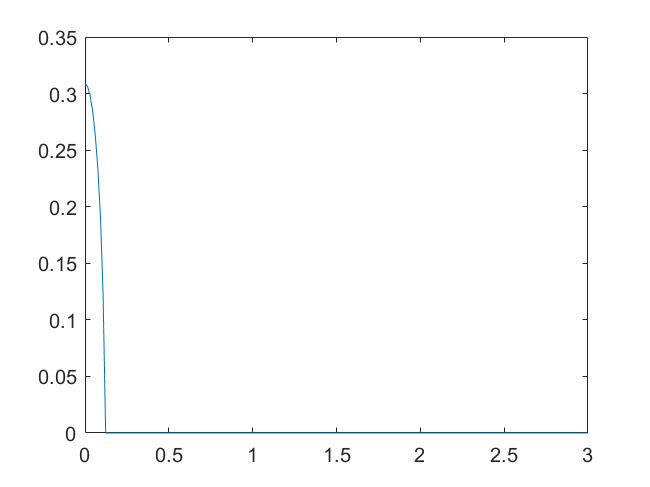


% for Bx, Bz, B
Bx1 = f1_1 + f3_1;
Bz1 = f2_1 + f4_1;
B1 = (Bx1.^2 + Bz1.^2).^(0.5);

Bx2 = f1_2 + f3_2;
Bz2 = f2_2 + f4_2;
B2 = (Bx2.^2 + Bz2.^2).^(0.5);

Bx3 = f1_3 + f3_3;
Bz3 = f2_3 + f4_3;
B3 = (Bx3.^2 + Bz3.^2).^(0.5);

% for gradient
dBps_z_dx1 = -(1/2)*((Bz_max-Bz_min)/Lx).*((sech((-x + x0)./Lx)).^2);
dBps_x_dz1 = (B_lobe/Lz).*(sech(z./Lz)).^2;
BgradB1 = (1./B1).*((Bz1.^2).*dBps_z_dx1 - (Bx1.^2).*dBps_x_dz1);
grad1_1 = abs((Bz1.^2).*dBps_z_dx1);
grad2_1 = abs((Bx1.^2).*dBps_x_dz1);

dBps_z_dx2 = -(1/2)*((Bz_max-Bz_min)/Lx).*((sech((-x1 + x0)./Lx)).^2);
dBps_x_dz2 = (B_lobe/Lz).*(sech(z./Lz)).^2;
BgradB2 = (1./B2).*((Bz2.^2).*dBps_z_dx2 - (Bx2.^2).*dBps_x_dz2);
grad1_2 = abs((Bz2.^2).*dBps_z_dx2);
grad2_2 = abs((Bx2.^2).*dBps_x_dz2);

dBps_z_dx3 = -(1/2)*((Bz_max-Bz_min)/Lx).*((sech((-x2 + x0)./Lx)).^2);
dBps_x_dz3 = (B_lobe/Lz).*(sech(z./Lz)).^2;
BgradB3 = (1./B3).*((Bz3.^2).*dBps_z_dx3 - (Bx3.^2).*dBps_x_dz3);
grad1_3 = abs((Bz3.^2).*dBps_z_dx3);
grad2_3 = abs((Bx3.^2).*dBps_x_dz3);

%for (1+sin....)
a1_1 = 1 + ((sin(alpha_eq1))^2).*(B1./B_eq1);
a1_2 = 1 + ((sin(alpha_eq2))^2).*(B1./B_eq1);
a1_3 = 1 + ((sin(alpha_eq3))^2).*(B1./B_eq1);
a1_4 = 1 + ((sin(alpha_eq4))^2).*(B1./B_eq1);
a1_5 = 1 + ((sin(alpha_eq5))^2).*(B1./B_eq1);
a1_6 = 1 + ((sin(alpha_eq6))^2).*(B1./B_eq1);
a1_7 = 1 + ((sin(alpha_eq7))^2).*(B1./B_eq1);
a1_8 = 1 + ((sin(alpha_eq8))^2).*(B1./B_eq1);
a1_9 = 1 + ((sin(alpha_eq9))^2).*(B1./B_eq1);
a1_10 = 1 + ((sin(alpha_eq10))^2).*(B1./B_eq1);


a2_1 = 1 + ((sin(alpha_eq1))^2).*(B2./B_eq2);
a2_2 = 1 + ((sin(alpha_eq2))^2).*(B2./B_eq2);
a2_3 = 1 + ((sin(alpha_eq3))^2).*(B2./B_eq2);
a2_4 = 1 + ((sin(alpha_eq4))^2).*(B2./B_eq2);
a2_5 = 1 + ((sin(alpha_eq5))^2).*(B2./B_eq2);
a2_6 = 1 + ((sin(alpha_eq6))^2).*(B2./B_eq2);
a2_7 = 1 + ((sin(alpha_eq7))^2).*(B2./B_eq2);
a2_8 = 1 + ((sin(alpha_eq8))^2).*(B2./B_eq2);
a2_9 = 1 + ((sin(alpha_eq9))^2).*(B2./B_eq2);
a2_10 = 1 + ((sin(alpha_eq10))^2).*(B2./B_eq2);


a3_1 = 1 + ((sin(alpha_eq1))^2).*(B3./B_eq3);
a3_2 = 1 + ((sin(alpha_eq2))^2).*(B3./B_eq3);
a3_3 = 1 + ((sin(alpha_eq3))^2).*(B3./B_eq3);
a3_4 = 1 + ((sin(alpha_eq4))^2).*(B3./B_eq3);
a3_5 = 1 + ((sin(alpha_eq5))^2).*(B3./B_eq3);
a3_6 = 1 + ((sin(alpha_eq6))^2).*(B3./B_eq3);
a3_7 = 1 + ((sin(alpha_eq7))^2).*(B3./B_eq3);
a3_8 = 1 + ((sin(alpha_eq8))^2).*(B3./B_eq3);
a3_9 = 1 + ((sin(alpha_eq9))^2).*(B3./B_eq3);
a3_10 = 1 + ((sin(alpha_eq10))^2).*(B3./B_eq3);

%rhoe


    rhoe1  = (102*sqrt(EE4))/(B_eq1 * 6371);
    rhoe2 = (102*sqrt(EE4))/(B_eq2 * 6371);
    rhoe3 = (102*sqrt(EE4))/(B_eq3 * 6371);

    Vd_v1_1  = (1/2)*(rhoe1./(Lx)).*a1_1.*((BgradB1.*Lx)./(B_eq1^2));
    Vd_v1_2  = (1/2)*(rhoe1./(Lx)).*a1_2.*((BgradB1.*Lx)./(B_eq1^2));
    Vd_v1_3  = (1/2)*(rhoe1./(Lx)).*a1_3.*((BgradB1.*Lx)./(B_eq1^2));
    Vd_v1_4  = (1/2)*(rhoe1./(Lx)).*a1_4.*((BgradB1.*Lx)./(B_eq1^2));
    Vd_v1_5  = (1/2)*(rhoe1./(Lx)).*a1_5.*((BgradB1.*Lx)./(B_eq1^2));
    Vd_v1_6  = (1/2)*(rhoe1./(Lx)).*a1_6.*((BgradB1.*Lx)./(B_eq1^2));
    Vd_v1_7  = (1/2)*(rhoe1./(Lx)).*a1_7.*((BgradB1.*Lx)./(B_eq1^2));
    Vd_v1_8  = (1/2)*(rhoe1./(Lx)).*a1_8.*((BgradB1.*Lx)./(B_eq1^2));
    Vd_v1_9  = (1/2)*(rhoe1./(Lx)).*a1_9.*((BgradB1.*Lx)./(B_eq1^2));
    Vd_v1_10  = (1/2)*(rhoe1./(Lx)).*a1_10.*((BgradB1.*Lx)./(B_eq1^2));
    
    
    Vd_v2_1  = (1/2)*(rhoe2./(Lx)).*a2_1.*((BgradB2.*Lx)./(B_eq2^2));
    Vd_v2_2  = (1/2)*(rhoe2./(Lx)).*a2_2.*((BgradB2.*Lx)./(B_eq2^2));
    Vd_v2_3  = (1/2)*(rhoe2./(Lx)).*a2_3.*((BgradB2.*Lx)./(B_eq2^2));
    Vd_v2_4  = (1/2)*(rhoe2./(Lx)).*a2_4.*((BgradB2.*Lx)./(B_eq2^2));
    Vd_v2_5  = (1/2)*(rhoe2./(Lx)).*a2_5.*((BgradB2.*Lx)./(B_eq2^2));
    Vd_v2_6  = (1/2)*(rhoe2./(Lx)).*a2_6.*((BgradB2.*Lx)./(B_eq2^2));
    Vd_v2_7  = (1/2)*(rhoe2./(Lx)).*a2_7.*((BgradB2.*Lx)./(B_eq2^2));
    Vd_v2_8  = (1/2)*(rhoe2./(Lx)).*a2_8.*((BgradB2.*Lx)./(B_eq2^2));
    Vd_v2_9  = (1/2)*(rhoe2./(Lx)).*a2_9.*((BgradB2.*Lx)./(B_eq2^2));
    Vd_v2_10  = (1/2)*(rhoe2./(Lx)).*a2_10.*((BgradB2.*Lx)./(B_eq2^2));
    
    
    Vd_v3_1  = (1/2)*(rhoe3./(Lx)).*a3_1.*((BgradB3.*Lx)./(B_eq3^2));
    Vd_v3_2  = (1/2)*(rhoe3./(Lx)).*a3_2.*((BgradB3.*Lx)./(B_eq3^2));
    Vd_v3_3  = (1/2)*(rhoe3./(Lx)).*a3_3.*((BgradB3.*Lx)./(B_eq3^2));
    Vd_v3_4  = (1/2)*(rhoe3./(Lx)).*a3_4.*((BgradB3.*Lx)./(B_eq3^2));
    Vd_v3_5  = (1/2)*(rhoe3./(Lx)).*a3_5.*((BgradB3.*Lx)./(B_eq3^2));
    Vd_v3_6  = (1/2)*(rhoe3./(Lx)).*a3_6.*((BgradB3.*Lx)./(B_eq3^2));
    Vd_v3_7  = (1/2)*(rhoe3./(Lx)).*a3_7.*((BgradB3.*Lx)./(B_eq3^2));
    Vd_v3_8  = (1/2)*(rhoe3./(Lx)).*a3_8.*((BgradB3.*Lx)./(B_eq3^2));
    Vd_v3_9  = (1/2)*(rhoe3./(Lx)).*a3_9.*((BgradB3.*Lx)./(B_eq3^2));
    Vd_v3_10  = (1/2)*(rhoe3./(Lx)).*a3_10.*((BgradB3.*Lx)./(B_eq3^2));
    
   

v_par = (1 - (B2./B_eq2) .* sin(alpha_eq8)^2 ).^(1/2);
plot (z, v_par)



%for V_D/v


%--------
%------- x0 - Lx
Vd_v_a = [Vd_v1_1, Vd_v1_2, Vd_v1_3, Vd_v1_4, Vd_v1_5, Vd_v1_6, Vd_v1_7, Vd_v1_8, Vd_v1_9, Vd_v1_10];
theSum1 = 0;
theSum2 = 0;
theSum3 = 0;
theSum4 = 0;
theSum5 = 0;
theSum6 = 0;
theSum7 = 0;
theSum8 = 0;
theSum9 = 0;
theSum10 = 0;

for i = 1:105
  theSum1 = theSum1 + ((B1./Bz1).*Vd_v_a(i,1));
  end
theSum_1 = sum (theSum1);

for i = 1:75
  theSum2 = theSum2 + ((B1./Bz1).*Vd_v_a(i,2));
  end
theSum_2 = sum (theSum2);

for i = 1:58
  theSum3 = theSum3 + ((B1./Bz1).*Vd_v_a(i,3));
  end
theSum_3 = sum (theSum3);

for i = 1:48
  theSum4 = theSum4 + ((B1./Bz1).*Vd_v_a(i,4));
  end
theSum_4 = sum (theSum4);

for i = 1:36
  theSum5 = theSum5 + ((B1./Bz1).*Vd_v_a(i,5));
  end
theSum_5 = sum (theSum5);

for i = 1:30
  theSum6 = theSum6 + ((B1./Bz1).*Vd_v_a(i,6));
  end
theSum_6 = sum (theSum6);

for i = 1:20
  theSum7 = theSum7 + ((B1./Bz1).*Vd_v_a(i,7));
  end
theSum_7 = sum (theSum7);

for i = 1:9
  theSum8 = theSum8 + ((B1./Bz1).*Vd_v_a(i,8));
  end
theSum_8 = sum (theSum8);

for i = 1:6
  theSum9 = theSum9 + ((B1./Bz1).*Vd_v_a(i,9));
  end
theSum_9 = sum (theSum9);

for i = 1:4
  theSum10 = theSum10 + ((B1./Bz1).*Vd_v_a(i,10));
  end
theSum_10 = sum (theSum10);



%const1 = -2 *(B_eq1/(sin(alpha_eq))^2)
z=T(1:step:ld);
dz = 0;
dB = 0;
k = 1;
dz_dB = 0;
for i = 1 : 104
    dz (k)  = abs(z(k+1)-z(k));
    dB (k) = abs(B1(k+1) - B1(k));
    dz_dB  = dz_dB + dz(k)/dB(k);
    
    k = k+1;
end
dz_dB1 = dz_dB/104;

theSum1 = 0;
for i = 1:105
  theSum1 = theSum1 + (B1./Bz1);
end
theSum1_1 = sum (theSum1);

theSum2 = 0;
for i = 1:75
  theSum2 = theSum2 + (B1./Bz1);
end
theSum1_2 = sum (theSum2);

theSum3 = 0;
for i = 1:58
  theSum3 = theSum3 + (B1./Bz1);
end
theSum1_3 = sum (theSum3);

theSum4 = 0;
for i = 1:48
  theSum4 = theSum4 + (B1./Bz1);
end
theSum1_4 = sum (theSum4);

theSum5 = 0;
for i = 1:36
  theSum5 = theSum5 + (B1./Bz1);
end
theSum1_5 = sum (theSum5);

theSum6 = 0;
for i = 1:30
  theSum6 = theSum6 + (B1./Bz1);
end
theSum1_6 = sum (theSum6);

theSum7 = 0;
for i = 1:20
  theSum7 = theSum7 + (B1./Bz1);
end
theSum1_7 = sum (theSum7);

theSum8 = 0;
for i = 1:9
  theSum8 = theSum8 + (B1./Bz1);
end
theSum1_8 = sum (theSum8);

theSum9 = 0;
for i = 1:6
  theSum9 = theSum9 + (B1./Bz1);
end
theSum1_9 = sum (theSum9);

theSum10 = 0;
for i = 1:4
  theSum10 = theSum10 + (B1./Bz1);
end
theSum1_10 = sum (theSum10);

v1 = (theSum_1.*dz_dB1)./(theSum1_1.*dz_dB1)

v1 = -0.0165

v2 = (theSum_2.*dz_dB1)./(theSum1_2.*dz_dB1)

v2 = -0.0259

v3 = (theSum_3.*dz_dB1)./(theSum1_3.*dz_dB1)

v3 = -0.0328

v4 = (theSum_4.*dz_dB1)./(theSum1_4.*dz_dB1)

v4 = -0.0343

v5 = (theSum_5.*dz_dB1)./(theSum1_5.*dz_dB1)

v5 = -0.0329

v6 = (theSum_6.*dz_dB1)./(theSum1_6.*dz_dB1)

v6 = -0.0321

v7 = (theSum_7.*dz_dB1)./(theSum1_7.*dz_dB1)

v7 = -0.0282

v8 = (theSum_8.*dz_dB1)./(theSum1_8.*dz_dB1)

v8 = -0.0145

v9 = (theSum_9.*dz_dB1)./(theSum1_9.*dz_dB1)

v9 = -0.0110

v10 = (theSum_10.*dz_dB1)./(theSum1_10.*dz_dB1)

v10 = -0.0095


v_m1 = [v1 v2 v3 v4 v5 v6 v7 v8 v9 v10];

%--------------------
% x0
Vd_v_b = [Vd_v2_1, Vd_v2_2, Vd_v2_3, Vd_v2_4, Vd_v2_5, Vd_v2_6, Vd_v2_7, Vd_v2_8, Vd_v2_9, Vd_v2_10];
theSum1_2 = 0;
theSum2_2 = 0;
theSum3_2 = 0;
theSum4_2 = 0;
theSum5_2 = 0;
theSum6_2 = 0;
theSum7_2 = 0;
theSum8_2 = 0;
theSum9_2 = 0;
theSum10_2 = 0;

for i = 1:100
  theSum1_2 = theSum1_2 + ((B2./Bz2).*Vd_v_b(i,1));
    
end
theSum_1_2 = sum (theSum1_2);

for i = 1:71
  theSum2_2 = theSum2_2 + ((B2./Bz2).*Vd_v_b(i,2));
    
end
theSum_2_2 = sum (theSum2_2);

for i = 1:54
  theSum3_2 = theSum3_2 + ((B2./Bz2).*Vd_v_b(i,3));
    
end
theSum_3_2 = sum (theSum3_2);

for i = 1:45
  theSum4_2 = theSum4_2 + ((B2./Bz2).*Vd_v_b(i,4));
    
end
theSum_4_2 = sum (theSum4_2);

for i = 1:32
  theSum5_2 = theSum5_2 + ((B2./Bz2).*Vd_v_b(i,5));
    
end
theSum_5_2 = sum (theSum5_2);

for i = 1:24
  theSum6_2 = theSum6_2 + ((B2./Bz2).*Vd_v_b(i,6));
    
end
theSum_6_2 = sum (theSum6_2);

for i = 1:16
  theSum7_2 = theSum7_2 + ((B2./Bz2).*Vd_v_b(i,7));
    
end
theSum_7_2 = sum (theSum7_2);

for i = 1:9
  theSum8_2 = theSum8_2 + ((B2./Bz2).*Vd_v_b(i,8));
    
end
theSum_8_2 = sum (theSum8_2);

for i = 1:6
  theSum9_2 = theSum9_2 + ((B2./Bz2).*Vd_v_b(i,9));
    
end
theSum_9_2 = sum (theSum9_2);

for i = 1:4
  theSum10_2 = theSum10_2 + ((B2./Bz2).*Vd_v_b(i,10));
    
end
theSum_10_2 = sum (theSum10_2);




%const2 = -2 *(B_eq1/(sin(alpha_eq))^2)
z=T(1:step:ld);
dz2 = 0;
dB2 = 0;
k2 = 1;
dz_dB2 = 0;
for i2 = 1 : 104
    dz2 (k2)  = abs(z(k2+1)-z(k2));
    dB2 (k2) = abs(B2(k2+1) - B2(k2));
    dz_dB2  = dz_dB2 + dz2(k2)/dB2(k2);
    
    k2 = k2+1;
end
dz_dB2 = dz_dB2/104;

theSum1 = 0;
for i2 = 1:100
  theSum1 = theSum1 + (B2./Bz2);
end
theSum1_2 = sum (theSum1);

theSum2 = 0;
for i2 = 1:71
  theSum2 = theSum2 + (B2./Bz2);
end
theSum2_2 = sum (theSum2);

theSum3 = 0;
for i2 = 1:54
  theSum3 = theSum3 + (B2./Bz2);
end
theSum3_2 = sum (theSum3);

theSum4 = 0;
for i2 = 1:45
  theSum4 = theSum4 + (B2./Bz2);
end
theSum4_2 = sum (theSum4);

theSum5 = 0;
for i2 = 1:32
  theSum5 = theSum5 + (B2./Bz2);
end
theSum5_2 = sum (theSum5);

theSum6 = 0;
for i2 = 1:24
  theSum6 = theSum6 + (B2./Bz2);
end
theSum6_2 = sum (theSum6);

theSum7 = 0;
for i2 = 1:16
  theSum7 = theSum7 + (B2./Bz2);
end
theSum7_2 = sum (theSum7);

theSum8 = 0;
for i2 = 1:9
  theSum8 = theSum8 + (B2./Bz2);
end
theSum8_2 = sum (theSum8);

theSum9 = 0;
for i2 = 1:6
  theSum9 = theSum9 + (B2./Bz2);
end
theSum9_2 = sum (theSum9);

theSum10 = 0;
for i2 = 1:4
  theSum10 = theSum10 + (B2./Bz2);
end
theSum10_2 = sum (theSum10);

v1_2 = (theSum_1_2.*dz_dB2)./(theSum1_2.*dz_dB2)

v1_2 = -0.0234

v2_2 = (theSum_2_2.*dz_dB2)./(theSum2_2.*dz_dB2)

v2_2 = -0.0368

v3_2 = (theSum_3_2.*dz_dB2)./(theSum3_2.*dz_dB2)

v3_2 = -0.0444

v4_2 = (theSum_4_2.*dz_dB2)./(theSum4_2.*dz_dB2)

v4_2 = -0.0454

v5_2 = (theSum_5_2.*dz_dB2)./(theSum5_2.*dz_dB2)

v5_2 = -0.0413

v6_2 = (theSum_6_2.*dz_dB2)./(theSum6_2.*dz_dB2)

v6_2 = -0.0383

v7_2 = (theSum_7_2.*dz_dB2)./(theSum7_2.*dz_dB2)

v7_2 = -0.0363

v8_2 = (theSum_8_2.*dz_dB2)./(theSum8_2.*dz_dB2)

v8_2 = -0.0358

v9_2 = (theSum_9_2.*dz_dB2)./(theSum9_2.*dz_dB2)

v9_2 = -0.0350

v10_2 = (theSum_10_2.*dz_dB2)./(theSum10_2.*dz_dB2)

v10_2 = -0.0345


v_m2 = [v1_2 v2_2 v3_2 v4_2 v5_2 v6_2 v7_2 v8_2 v9_2 v10_2];

%--------
% x0 + Lx

Vd_v_c = [Vd_v3_1, Vd_v3_2, Vd_v3_3, Vd_v3_4, Vd_v3_5, Vd_v3_6, Vd_v3_7, Vd_v3_8, Vd_v3_9, Vd_v3_10] ;
theSum1_3 = 0;
theSum2_3 = 0;
theSum3_3 = 0;
theSum4_3 = 0;
theSum5_3 = 0;
theSum6_3 = 0;
theSum7_3 = 0;
theSum8_3 = 0;
theSum9_3 = 0;
theSum10_3 = 0;

for i = 1:94
  theSum1_3 = theSum1_3 + ((B3./Bz3).*Vd_v_c(i,1));
   
end
theSum_1_3 = sum (theSum1_3);

for i = 1:67
  theSum2_3 = theSum2_3 + ((B3./Bz3).*Vd_v_c(i,2));
   
end
theSum_2_3 = sum (theSum2_3);

for i = 1:50
  theSum3_3 = theSum3_3 + ((B3./Bz3).*Vd_v_c(i,3));
   
end
theSum_3_3 = sum (theSum3_3);

for i = 1:39
  theSum4_3 = theSum4_3 + ((B3./Bz3).*Vd_v_c(i,4));
   
end
theSum_4_3 = sum (theSum4_3);

for i = 1:27
  theSum5_3 = theSum5_3 + ((B3./Bz3).*Vd_v_c(i,5));
   
end
theSum_5_3 = sum (theSum5_3);

for i = 1:19
  theSum6_3 = theSum6_3 + ((B3./Bz3).*Vd_v_c(i,6));
   
end
theSum_6_3 = sum (theSum6_3);

for i = 1:12
  theSum7_3 = theSum7_3 + ((B3./Bz3).*Vd_v_c(i,7));
   
end
theSum_7_3 = sum (theSum7_3);

for i = 1:7
  theSum8_3 = theSum8_3 + ((B3./Bz3).*Vd_v_c(i,8));
   
end
theSum_8_3 = sum (theSum8_3);

for i = 1:6
  theSum9_3 = theSum9_3 + ((B3./Bz3).*Vd_v_c(i,9));
   
end
theSum_9_3 = sum (theSum9_3);

for i = 1:3
  theSum10_3 = theSum10_3 + ((B3./Bz3).*Vd_v_c(i,10));
   
end
theSum_10_3 = sum (theSum10_3);




%const3 = -2 *(B_eq1/(sin(alpha_eq))^2)
z=T(1:step:ld);
dz3 = 0;
dB3 = 0;
k3 = 1;
dz_dB3 = 0;
for i3 = 1 : 104
    dz3 (k3)  = abs(z(k3+1)-z(k3));
    dB3 (k3) = abs(B3(k3+1) - B3(k3));
    dz_dB3  = dz_dB3 + dz3(k3)/dB3(k3);
    
    k3 = k3+1;
end
dz_dB3 = dz_dB3/104;

theSum1 = 0;
for i3 = 1:94
  theSum1 = theSum1 + (B3./Bz3);
end
theSum1_3 = sum (theSum1);

theSum2 = 0;
for i3 = 1:67
  theSum2 = theSum2 + (B3./Bz3);
end
theSum2_3 = sum (theSum2);

theSum3 = 0;
for i3 = 1:50
  theSum3 = theSum3 + (B3./Bz3);
end
theSum3_3 = sum (theSum3);

theSum4 = 0;
for i3 = 1:39
  theSum4 = theSum4 + (B3./Bz3);
end
theSum4_3 = sum (theSum4);

theSum5 = 0;
for i3 = 1:27
  theSum5 = theSum5 + (B3./Bz3);
end
theSum5_3 = sum (theSum5);

theSum6 = 0;
for i3 = 1:19
  theSum6 = theSum6 + (B3./Bz3);
end
theSum6_3 = sum (theSum6);

theSum7 = 0;
for i3 = 1:12
  theSum7 = theSum7 + (B3./Bz3);
end
theSum7_3 = sum (theSum7);

theSum8 = 0;
for i3 = 1:7
  theSum8 = theSum8 + (B3./Bz3);
end
theSum8_3 = sum (theSum8);

theSum9 = 0;
for i3 = 1:6
  theSum9 = theSum9 + (B3./Bz3);
end
theSum9_3 = sum (theSum9);

theSum10 = 0;
for i3 = 1:3
  theSum10 = theSum10 + (B3./Bz3);
end
theSum10_3 = sum (theSum10);

v1_3 = (theSum_1_3.*dz_dB3)./(theSum1_3.*dz_dB3)

v1_3 = -0.0314

v2_3 = (theSum_2_3.*dz_dB3)./(theSum2_3.*dz_dB3)

v2_3 = -0.0486

v3_3 = (theSum_3_3.*dz_dB3)./(theSum3_3.*dz_dB3)

v3_3 = -0.0544

v4_3 = (theSum_4_3.*dz_dB3)./(theSum4_3.*dz_dB3)

v4_3 = -0.0499

v5_3 = (theSum_5_3.*dz_dB3)./(theSum5_3.*dz_dB3)

v5_3 = -0.0406

v6_3 = (theSum_6_3.*dz_dB3)./(theSum6_3.*dz_dB3)

v6_3 = -0.0315

v7_3 = (theSum_7_3.*dz_dB3)./(theSum7_3.*dz_dB3)

v7_3 = -0.0219

v8_3 = (theSum_8_3.*dz_dB3)./(theSum8_3.*dz_dB3)

v8_3 = -0.0156

v9_3 = (theSum_9_3.*dz_dB3)./(theSum9_3.*dz_dB3)

v9_3 = -0.0148

v10_3 = (theSum_10_3.*dz_dB3)./(theSum10_3.*dz_dB3)

v10_3 = -0.0127

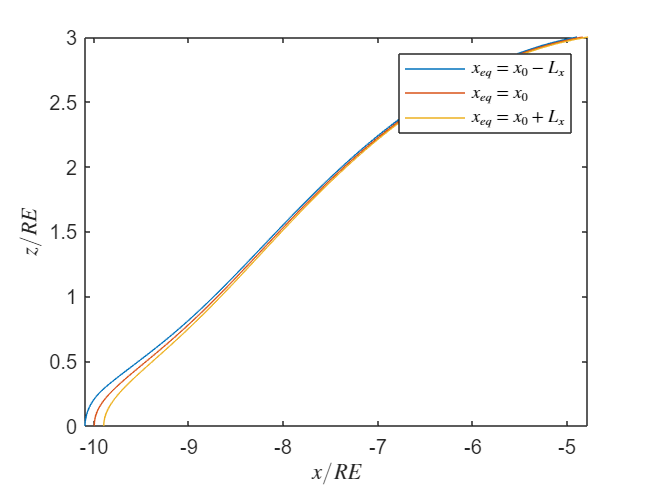


v_m3 = [v1_3 v2_3 v3_3 v4_3 v5_3 v6_3 v7_3 v8_3 v9_3 v10_3] ;

alpha_eq_m = [alpha_eq1 alpha_eq2 alpha_eq3 alpha_eq4 alpha_eq5 alpha_eq6 alpha_eq7 alpha_eq8 alpha_eq9 alpha_eq10];


% Plotting
figure
plot (x, z, x1, z, x2, z)
xlabel ('$x/RE$', 'interpreter', 'latex')
ylabel('$z/RE$', 'interpreter', 'latex') 
xlim('tight')
legend ('$x_{eq} = x_0 - L_x$', '$x_{eq} = x_0$', '$x_{eq} = x_0 + L_x$', 'interpreter', 'latex')

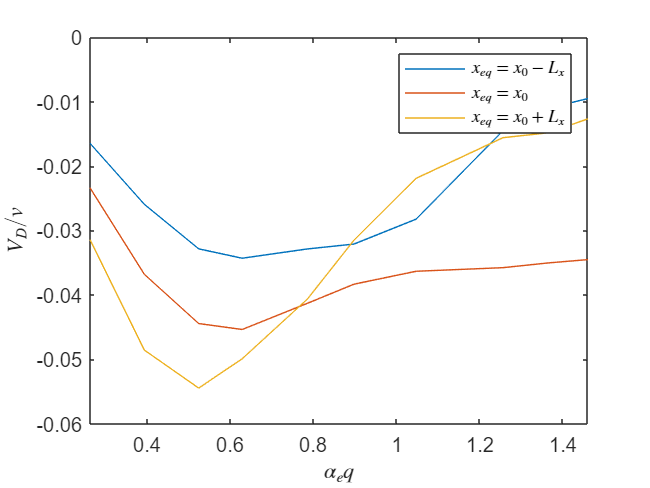


plot (alpha_eq_m, v_m1, alpha_eq_m, v_m2, alpha_eq_m, v_m3)
xlabel ('$\alpha_eq$', 'interpreter', 'latex')
ylabel('$V_{D}/v$', 'interpreter', 'latex') 
xlim('tight')
legend ('$x_{eq} = x_0 - L_x$', '$x_{eq} = x_0$', '$x_{eq} = x_0 + L_x$','interpreter', 'latex')

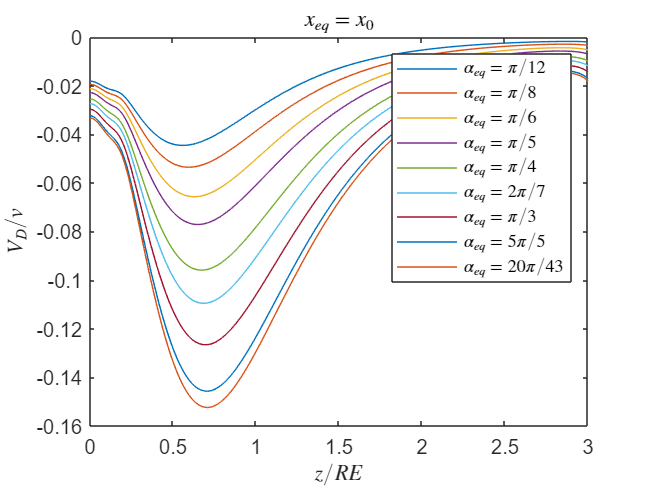


plot (z, Vd_v2_1, z, Vd_v2_2, z, Vd_v2_3,z, Vd_v2_4, z, Vd_v2_5,z, Vd_v2_6,z, Vd_v2_7, z, Vd_v2_8, z, Vd_v2_9)
xlabel ('$z/RE$', 'interpreter', 'latex')
ylabel('$V_{D}/v$', 'interpreter', 'latex') 
xlim('tight')
legend ('$\alpha_{eq} = \pi/12$', '$\alpha_{eq} = \pi/8$', '$\alpha_{eq} = \pi/6$', '$\alpha_{eq} = \pi/5$', '$\alpha_{eq} = \pi/4$', '$\alpha_{eq} = 2\pi/7$', '$\alpha_{eq} = \pi/3$', '$\alpha_{eq} = 5\pi/5$','$\alpha_{eq} = 20\pi/43$','interpreter','latex')
title('$x_{eq} = x_0$', 'interpreter', 'latex')

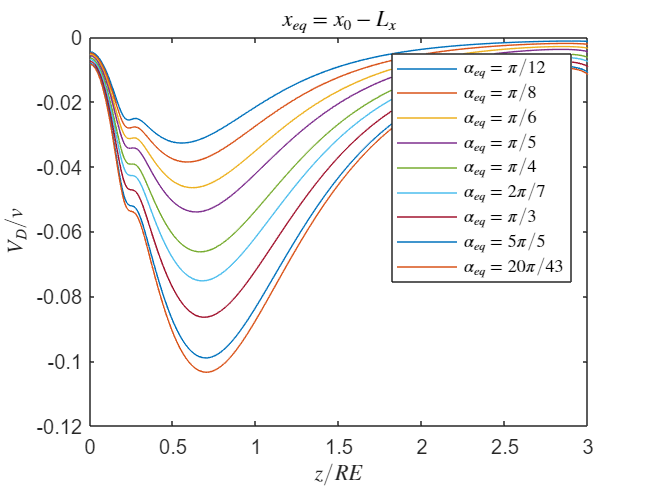


plot (z, Vd_v1_1, z, Vd_v1_2, z, Vd_v1_3,z, Vd_v1_4, z, Vd_v1_5,z, Vd_v1_6,z, Vd_v1_7,  z, Vd_v1_8, z, Vd_v1_9)
xlabel ('$z/RE$', 'interpreter', 'latex')
ylabel('$V_{D}/v$', 'interpreter', 'latex')  
xlim('tight')
legend ('$\alpha_{eq} = \pi/12$', '$\alpha_{eq} = \pi/8$', '$\alpha_{eq} = \pi/6$', '$\alpha_{eq} = \pi/5$', '$\alpha_{eq} = \pi/4$', '$\alpha_{eq} = 2\pi/7$', '$\alpha_{eq} = \pi/3$', '$\alpha_{eq} = 5\pi/5$','$\alpha_{eq} = 20\pi/43$','interpreter','latex')
title('$x_{eq} = x_0 - L_x$', 'interpreter', 'latex')

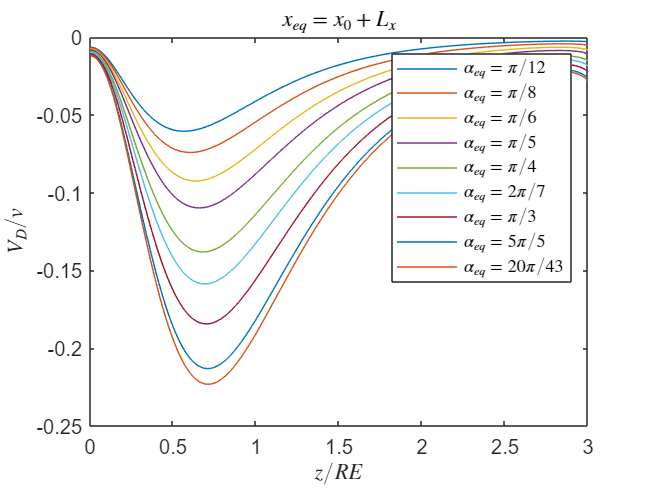


plot (z, Vd_v3_1, z, Vd_v3_2, z, Vd_v3_3,z, Vd_v3_4, z, Vd_v3_5,z, Vd_v3_6,z, Vd_v3_7,  z, Vd_v3_8, z, Vd_v3_9)
xlabel ('$z/RE$', 'interpreter', 'latex')
ylabel('$V_{D}/v$', 'interpreter', 'latex')  
xlim('tight')
legend ('$\alpha_{eq} = \pi/12$', '$\alpha_{eq} = \pi/8$', '$\alpha_{eq} = \pi/6$', '$\alpha_{eq} = \pi/5$', '$\alpha_{eq} = \pi/4$', '$\alpha_{eq} = 2\pi/7$', '$\alpha_{eq} = \pi/3$', '$\alpha_{eq} = 5\pi/5$','$\alpha_{eq} = 20\pi/43$','interpreter','latex')
title('$x_{eq} = x_0 + L_x$', 'interpreter', 'latex')

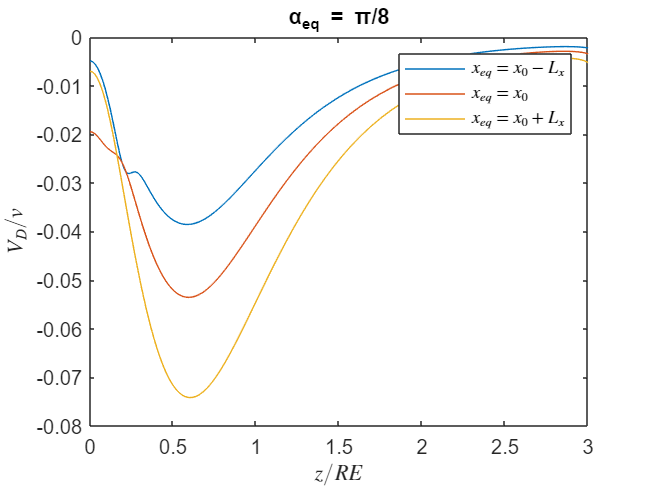


plot (z, Vd_v1_2, z, Vd_v2_2, z, Vd_v3_2)
xlabel ('$z/RE$', 'interpreter', 'latex')
ylabel('$V_{D}/v$', 'interpreter', 'latex') 
xlim('tight')
legend ('$x_{eq} = x_0 - L_x$','$x_{eq} = x_0$', '$x_{eq} = x_0 + L_x$', 'interpreter', 'latex')
title ('\alpha_{eq} = \pi/8')

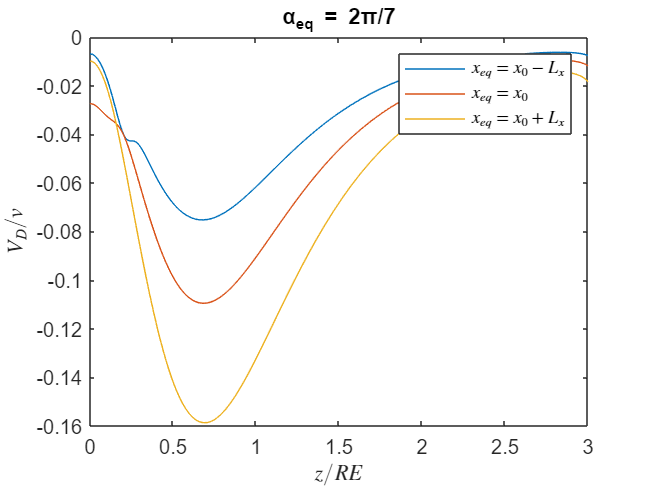


plot (z, Vd_v1_6, z, Vd_v2_6, z, Vd_v3_6)
xlabel ('$z/RE$', 'interpreter', 'latex')
ylabel('$V_{D}/v$', 'interpreter', 'latex') 
xlim('tight')
legend ('$x_{eq} = x_0 - L_x$','$x_{eq} = x_0$', '$x_{eq} = x_0 + L_x$', 'interpreter', 'latex')
title ('\alpha_{eq} = 2\pi/7')

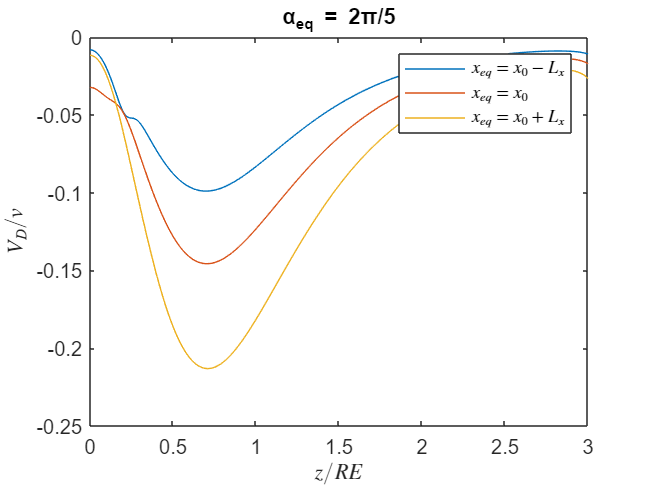


plot (z, Vd_v1_8, z, Vd_v2_8, z, Vd_v3_8)
xlabel ('$z/RE$', 'interpreter', 'latex')
ylabel('$V_{D}/v$', 'interpreter', 'latex') 
xlim('tight')
legend ('$x_{eq} = x_0 - L_x$','$x_{eq} = x_0$', '$x_{eq} = x_0 + L_x$', 'interpreter', 'latex')
title ('\alpha_{eq} = 2\pi/5')

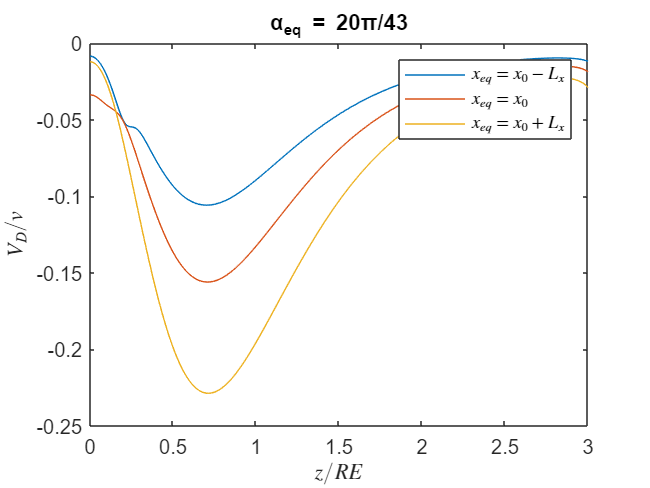


plot (z, Vd_v1_10, z, Vd_v2_10, z, Vd_v3_10)
xlabel ('$z/RE$', 'interpreter', 'latex')
ylabel('$V_{D}/v$', 'interpreter', 'latex') 
xlim('tight')
legend ('$x_{eq} = x_0 - L_x$','$x_{eq} = x_0$', '$x_{eq} = x_0 + L_x$', 'interpreter', 'latex')
title ('\alpha_{eq} = 20\pi/43')



x

x =   -10.0980
  -10.0975
  -10.0959
  -10.0933
  -10.0896
  -10.0848
  -10.0790
  -10.0722
  -10.0642
  -10.0565


function dy = bysyst(t,y)

dy = zeros(1,1);    % a column vector

global  Lx Lz  Bz_min Bz_max B_lobe  B_e x0;

%f1 = B_dip_x
%f2 = B_dip_z
%f3 = B_PS_x
%f4 = B_PS_z

f1 = (((B_e).*((1./sqrt((y.^2)+(t.^2))).^3).*(3.*y.*t))./((y.^2)+(t.^2)));
f2 = (((B_e).*((1./sqrt((y.^2)+(t.^2))).^3).*((2.*(t.^2)-(y.^2))./((y.^2)+(t.^2))))).*((0.5.* (1 + tanh( (y) +9) ) ));
f3 = (B_lobe.*tanh(t/Lz));
f4 = (Bz_min+(0.5).*(Bz_max-Bz_min).*(1+tanh((-y + x0)./ Lx)));




dy = (f1 + f3)./(f2 +f4);

end













